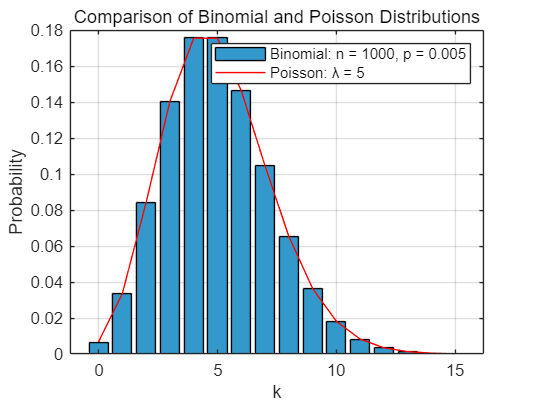

clear; clc; close all;

% binomial parameters
n = 1000;
p = 0.005;
% Poisson paremeters
lambda = n * p;
k = 0:15;
P_binomial = binopdf(k, n, p);
P_Poisson = poisspdf(k, lambda);
bar(k, P_binomial, 'FaceColor', [0.2 0.6 0.8], 'EdgeColor', 'k');
hold on;
plot(k, P_Poisson, 'r-');
xlabel('k');
ylabel('Probability');
title('Comparison of Binomial and Poisson Distributions');
grid on;
legend('Binomial: n = 1000, p = 0.005', 'Poisson: λ = 5');